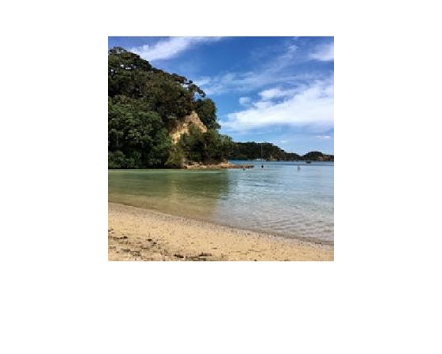

img1 = imread('file01.jpg');
img2 = imread('file02.jpg');
img3 = imread('file03.jpg');
imshow(img1)

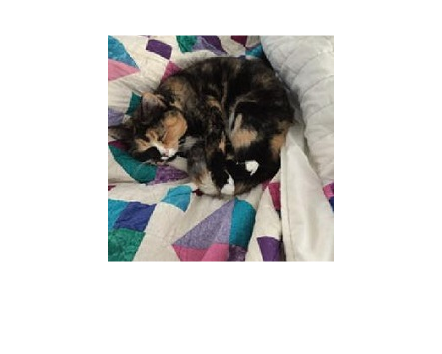

imshow(img2)

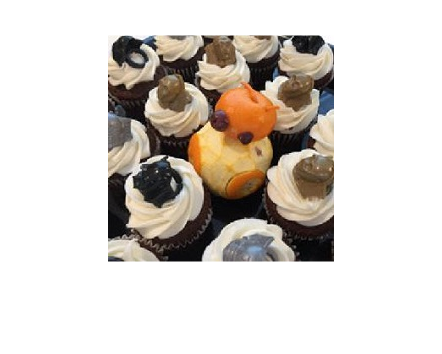

imshow(img3)

deepnet = alexnet

deepnet =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


ly = deepnet.Layers

ly =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    10  

inlayer = ly(1)

inlayer =   ImageInputLayer with properties:

                Name: 'data'
           InputSize: [227 227 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: [227×227×3 single]


outlayer = ly(end)

outlayer =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'



sz = inlayer.InputSize

sz =    227   227     3


categorynames = outlayer.ClassNames

categorynames = 1000×1 cell array
    {'tench'                         }
    {'goldfish'                      }
    {'great white shark'             }
    {'tiger shark'                   }
    {'hammerhead'                    }
    {'electric ray'                  }
    {'stingray'                      }
    {'cock'                          }
    {'hen'                           }
    {'ostrich'                       }
    {'brambling'                     }
    {'goldfinch'                     }
    {'house finch'                   }
    {'junco'                         }
    {'indigo bunting'                }
    {'robin'                         }
    {'bulbul'                        }
    {'jay'                           }
    {'magpie'                        }
    {'chickadee'                     }
    {'water ouzel'                   }
    {'kite'                          }
    {'bald eagle'                    }
    {'vulture'                       }
    {'great grey owl'         


img1 = img1(1:sz(1),1:sz(2),1:sz(3)); 
[pred1,scores] = classify(deepnet,img1)

pred1 = categorical
     seashore 


scores = 1×1000 single row vector
    0.0035    0.0000    0.0020    0.0043    0.0044    0.0130    0.0359    0.0000    0.0000    0.0003    0.0001    0.0001    0.0001    0.0005    0.0004    0.0000    0.0000    0.0002    0.0003    0.0001    0.0003    0.0012    0.0006    0.0001    0.0000    0.0003    0.0006    0.0001    0.0001    0.0009    0.0145    0.0009    0.0073    0.0492    0.6008    0.0034    0.0027    0.0001    0.0012    0.0211    0.0005    0.0026    0.0003    0.0021    0.0013    0.0045    0.0012    0.0180    0.0007    0.0158


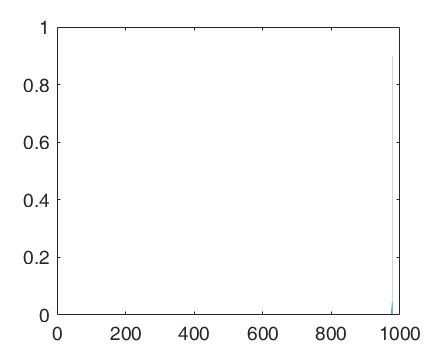


bar(scores)


%highscores = scores > 0.01 % return true or false when match
thresh = median(scores) + std(scores);
highscores = scores > thresh

highscores = 1×1000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


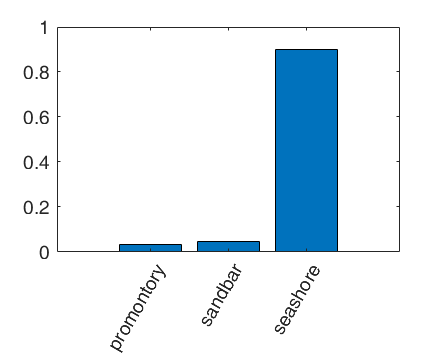


bar(scores(highscores))
xticks(1:length(scores(highscores)))
xticklabels(categorynames(highscores))
xtickangle(60)

ls *.jpg


file01.jpg  file02.jpg  file03.jpg  



net = alexnet

net =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


inlayer = ly(1)

inlayer =   ImageInputLayer with properties:

                Name: 'data'
           InputSize: [227 227 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: [227×227×3 single]


outlayer = ly(end)

outlayer =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


categorynames = outlayer.ClassNames

categorynames = 1000×1 cell array
    {'tench'                         }
    {'goldfish'                      }
    {'great white shark'             }
    {'tiger shark'                   }
    {'hammerhead'                    }
    {'electric ray'                  }
    {'stingray'                      }
    {'cock'                          }
    {'hen'                           }
    {'ostrich'                       }
    {'brambling'                     }
    {'goldfinch'                     }
    {'house finch'                   }
    {'junco'                         }
    {'indigo bunting'                }
    {'robin'                         }
    {'bulbul'                        }
    {'jay'                           }
    {'magpie'                        }
    {'chickadee'                     }
    {'water ouzel'                   }
    {'kite'                          }
    {'bald eagle'                    }
    {'vulture'                       }
    {'great grey owl'         


sz = inlayer.InputSize

sz =    227   227     3



imds = imageDatastore('file*.jpg')

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\file01.jpg';
                              'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\file02.jpg';
                              'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\file03.jpg'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


auds = augmentedImageDatastore([227 227], imds)

auds =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 3
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0



fname = auds.Files

fname = 3×1 cell array
    {'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\file01.jpg'}
    {'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\file02.jpg'}
    {'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\file03.jpg'}



img = readimage(auds,1)% read first image in datastore

img = 227×227×3 uint8 array
img(:,:,1) =

   230   228   228   230   231   230   230   232   232   232   230   231   229   229   230   230   232   231   231   232   233   231   232   233   235   234   236   236   238   239   239   238   238   238   239   238   238   239   238   234   235   234   233   232   232   233   234   233   235   234   232   232   231   231   231   231   233   231   233   235   232   236   241   241   243   245   243   243   242   242   244   247   245   245   244   243   245   245   243   244   247   247   247   248   247   246   243   243   242   242   241   242   241   240   238   236   234   236   235   236   240   237   236   240   244   241   244   245   245   245   248   245   243   237   236   237   232   232   234   229   227   228   228   228   227   227   228   228   225   224   225   226   227   226   225   225   226   226   225   224   225   227   227   226   228   228   228   228   228   228   226   226   225   225   225   225   224   224   224   2


[preds,scores] = classify(net,auds)

preds = 3×1 categorical array
     seashore 
     toy terrier 
     acorn squash 


scores = 3×1000 single matrix
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000


maxnum = max(scores,[],2)% return max number every row

maxnum = 3×1 single column vector
    0.8996
    0.1913
    0.0820


score = 1×1000 single row vector
    0.0000    0.0024    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0005    0.0000    0.0000    0.0000    0.0002    0.0000    0.0001    0.0005    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


thresh = single
0.0052

highscores = 1×1000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


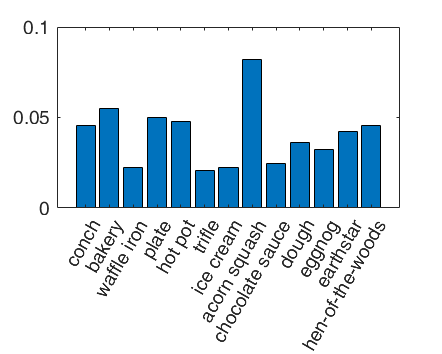

for i = 3
    score = scores(i,:)
    thresh = median(score + std(score))
    highscores = score > 0.02
    bar(score(highscores))
    
    
    xticks(1:length(score(highscores)))
    xticklabels(categorynames(highscores))
    xtickangle(60)
    
end

img = imread('file01.jpg')

img = 227×227×3 uint8 array
img(:,:,1) =

   230   228   228   230   231   230   230   232   232   232   230   231   229   229   230   230   232   231   231   232   233   231   232   233   235   234   236   236   238   239   239   238   238   238   239   238   238   239   238   234   235   234   233   232   232   233   234   233   235   234   232   232   231   231   231   231   233   231   233   235   232   236   241   241   243   245   243   243   242   242   244   247   245   245   244   243   245   245   243   244   247   247   247   248   247   246   243   243   242   242   241   242   241   240   238   236   234   236   235   236   240   237   236   240   244   241   244   245   245   245   248   245   243   237   236   237   232   232   234   229   227   228   228   228   227   227   228   228   225   224   225   226   227   226   225   225   226   226   225   224   225   227   227   226   228   228   228   228   228   228   226   226   225   225   225   225   224   224   224   2

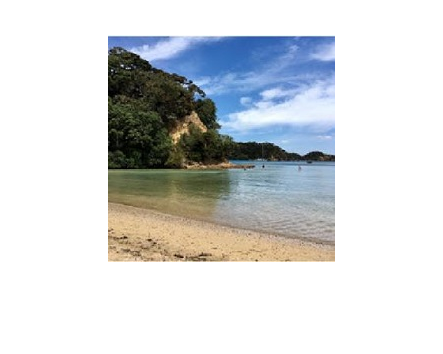

imshow(img)


sz = size(img)

sz =    227   227     3



img = imresize(img,[227 227]);
imshow(img)


net = alexnet

net =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


inlayer = ly(1)

inlayer =   ImageInputLayer with properties:

                Name: 'data'
           InputSize: [227 227 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: [227×227×3 single]


outlayer = ly(end)

outlayer =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


categorynames = outlayer.ClassNames

categorynames = 1000×1 cell array
    {'tench'                         }
    {'goldfish'                      }
    {'great white shark'             }
    {'tiger shark'                   }
    {'hammerhead'                    }
    {'electric ray'                  }
    {'stingray'                      }
    {'cock'                          }
    {'hen'                           }
    {'ostrich'                       }
    {'brambling'                     }
    {'goldfinch'                     }
    {'house finch'                   }
    {'junco'                         }
    {'indigo bunting'                }
    {'robin'                         }
    {'bulbul'                        }
    {'jay'                           }
    {'magpie'                        }
    {'chickadee'                     }
    {'water ouzel'                   }
    {'kite'                          }
    {'bald eagle'                    }
    {'vulture'                       }
    {'great grey owl'         


sz = inlayer.InputSize

sz =    227   227     3



imds = imageDatastore('gray*.jpg','IncludeSubfolders',true)

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\HJ_NK\Documents\GitHub\MATLAB-test\deep learning\gray01.jpg'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


auds = augmentedImageDatastore([227 227], imds,'ColorPreprocessing','gray2rgb')

auds =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'gray2rgb'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0



insz = net.Layers(1).InputSize

insz =    227   227     3


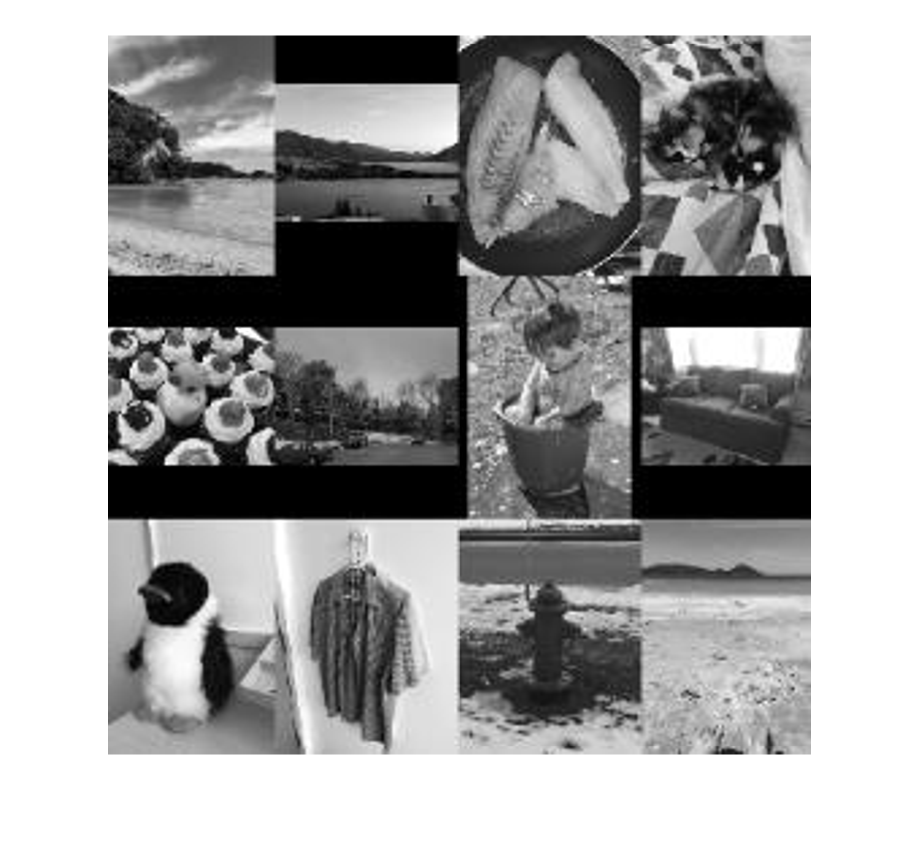


montage(imds)


preds = classify(net,auds)

preds = categorical
     abacus 


flwrds = imageDatastore('\','IncludeSubfolders',true,'LabelSource','foldernames')

flowernames = flwrds.Labels

[flwrTrain,flwrTest] = splitEachLabel(flwrds,0.6,'randomized')% 60% of the images to flwrTrain if the number big than 1 and is int, it represent how many images to flwrTrain

net = alexnet
layers = net.Layers

fc = fullyConnectedLayer(12) % creat a full connection layer with 12 nuroul

layers(23) = fc % replace old one

layers(end) = classificationLayer % replace output layer with a new blank output with no labels

opts = trainingOptions('sgdm','InitialLearnRate',0.001) % ains the default options for the training algorithm, “stochastic gradient descent with momentum”


%Get training images

flower_ds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');
[trainImgs,testImgs] = splitEachLabel(flower_ds,0.6);
numClasses = numel(categories(flower_ds.Labels));
 

%Create a network by modifying AlexNet

net = alexnet;
layers = net.Layers;
layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;
 

%Set training algorithm options

options = trainingOptions('sgdm','InitialLearnRate', 0.003,'Momentum',0.83);
 

%Perform training

[flowernet,info] = trainNetwork(trainImgs, layers, options);

Training on single GPU.
Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       14.06% |       3.6193 |          0.0030 |
|      13 |          50 |       00:02:03 |      100.00% |       0.0060 |          0.0030 |
|      25 |         100 |       00:04:06 |      100.00% |       0.0025 |          0.0030 |
|      30 |         120 |       00:04:56 |      100.00% |       0.0005 |          0.0030 |
|========================================================================================|


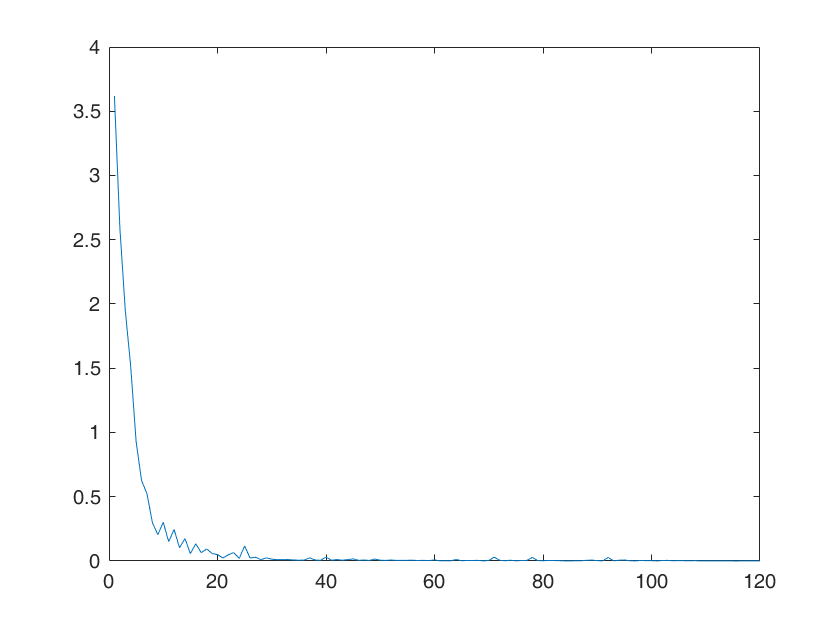

 

%Use trained network to classify test images

plot(info.TrainingLoss)


flwrPreds = classify(flowernet,testImgs);

flwrActual = testImgs.Labels;% find actual label in testimg

numCorrect = nnz(flwrPreds == flwrActual)% Count non-zero elements in an array. return the number of the matched elements in two array

numCorrect = 348


fracCorrect = numCorrect / numel(flwrPreds) % the correction persentation

fracCorrect = 0.9063

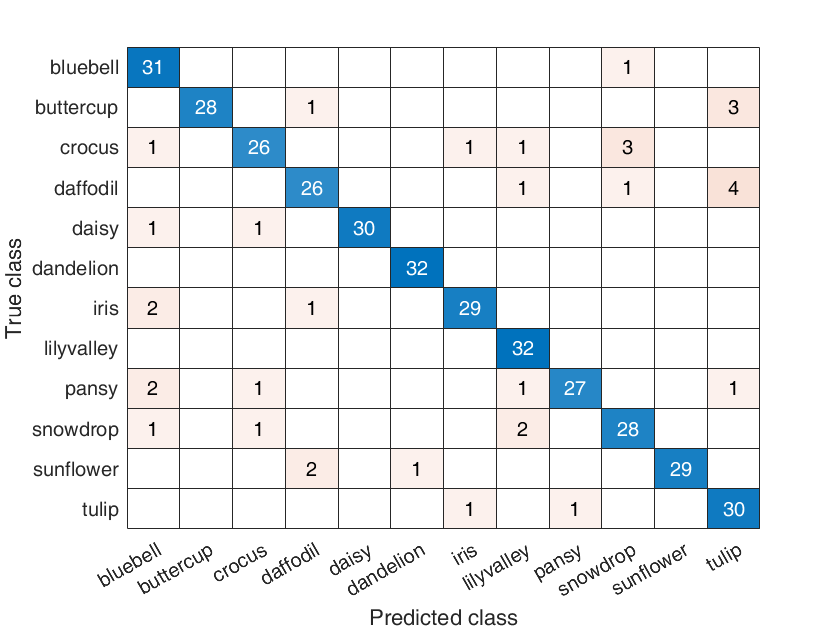

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [12×12 double]
         ClassLabels: [12×1 categorical]

  Show all properties



confusionchart(flwrActual,flwrPreds)

load myflowernet.m

Error using load
Number of columns on line 4 of ASCII file myflowernet.m must be the same as previous lines.

net = flowernet

inlayer = ly(1)
outlayer = ly(end)
categorynames = outlayer.ClassNames

sz = inlayer.InputSize

imds = imageDatastore('file*.jpg')
auds = augmentedImageDatastore([227 227], imds)

fname = auds.Files

img = readimage(auds,1)% read first image in datastore

[preds,scores] = classify(net,auds)

maxnum = max(scores,[],2)% return max number every row
for i = 4
    score = scores(i,:)
    thresh = median(score + std(score))
    highscores = score > 0.02
    bar(score(highscores))
    
    
    xticks(1:length(score(highscores)))
    xticklabels(categorynames(highscores))
    xtickangle(60)
    
end




